## Two-link planar (RR) 

### Rigid body tree

RR_robot = rigidBodyTree;
link1 = rigidBody('link1');
jnt1 = rigidBodyJoint('theta1','revolute');
link2 = rigidBody('link2');
jnt2 = rigidBodyJoint('theta2','revolute');

L1 = 0.3;
L2 = 0.15;
dhparams = [L1 0 0 0;
            L2 0 0 0];

setFixedTransform(jnt1,dhparams(1,:),'dh');
link1.Joint = jnt1;
addBody(RR_robot,link1,'base')

setFixedTransform(jnt2,dhparams(2,:),'dh');
link2.Joint = jnt2;
addBody(RR_robot,link2,'link1')
end_effector = rigidBody('end_effector');
addBody(RR_robot,end_effector,'link2');

RR_robot.DataFormat = 'column';

### Forward Kinematics

theta =  [pi/2; 0];
transform = getTransform(RR_robot,theta,'end_effector','base')

transform =     0.0000   -1.0000         0    0.0000
    1.0000    0.0000         0    0.4500
         0         0    1.0000         0
         0         0         0    1.0000


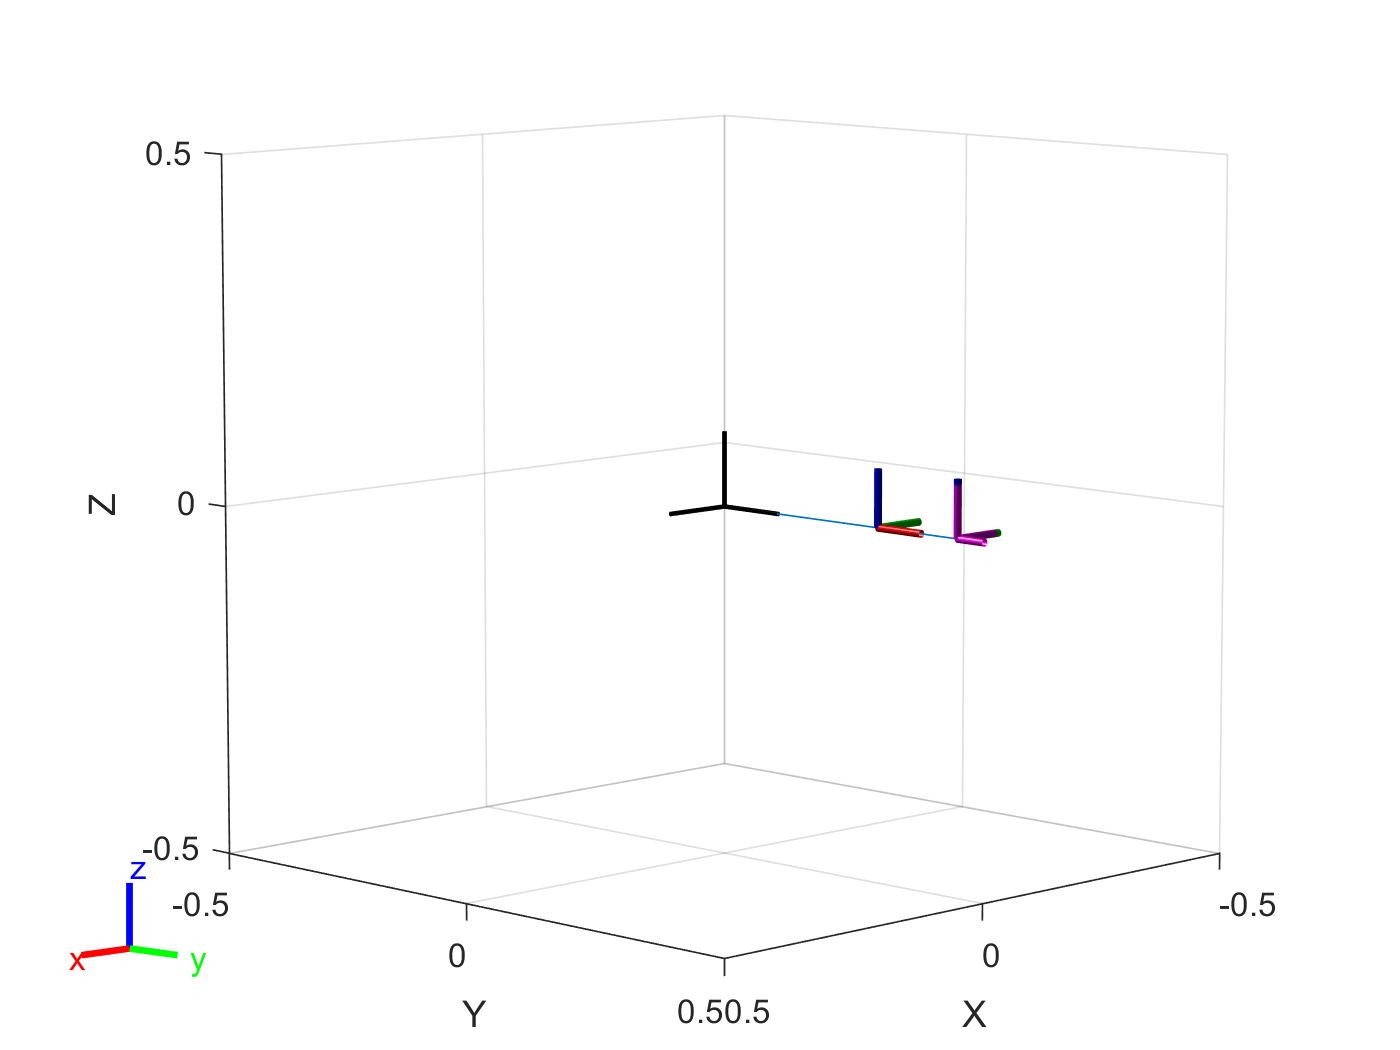

ans =   Axes (Primary) with properties:

             XLim: [-0.5000 0.5000]
             YLim: [-0.5000 0.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(RR_robot,theta)

#### closed form Forward kinematics (end effector)

XE = L2.*cos(theta(1)+theta(2))+L1.*cos(theta(1));
YE = L2.*sin(theta(1)+theta(2))+L1.*sin(theta(1));

### Inverse Kinematics

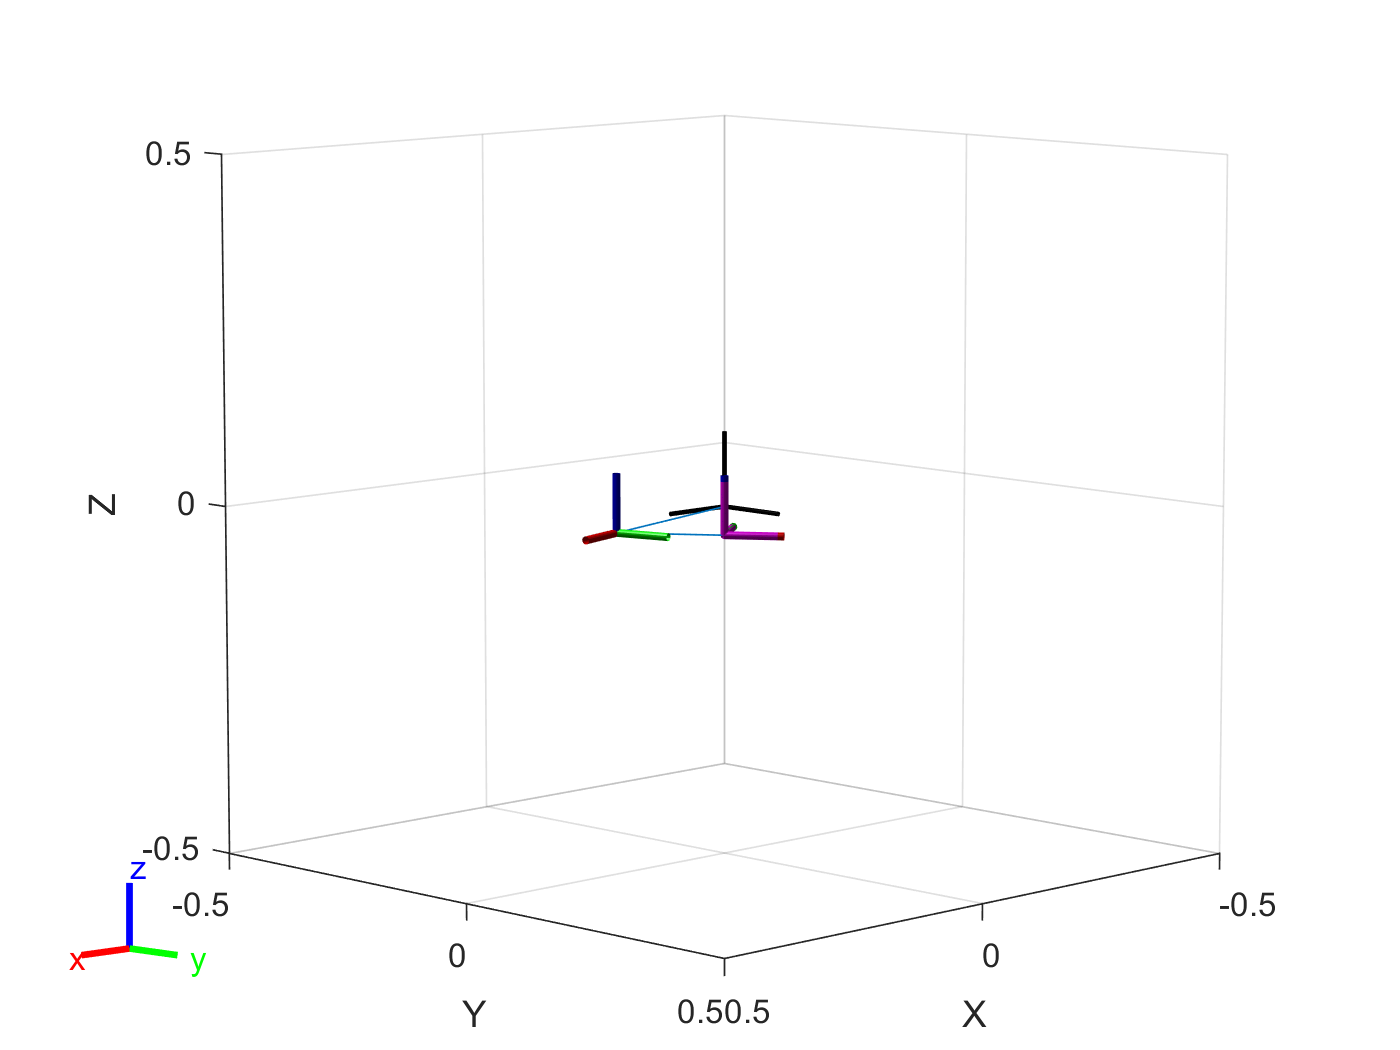

ik = robotics.InverseKinematics('RigidBodyTree',RR_robot,'SolverAlgorithm','LevenbergMarquardt');
initialguess = RR_robot.homeConfiguration;
weights = [0 0 0 1 1 0];
pos = trvec2tform([0.2001 0.2001 0]);
[soln,info] = ik('end_effector',pos,weights,initialguess);
show(RR_robot,soln);

#### Analytical IK

x = 0; y = 0.45;
tmp = (x^2+y^2-L1^2-L2^2)/(2*L1*L2);
q2 = acos(vpa(tmp,4))

$$q2 = 0.0$$

q1 = atan2(y,x)-atan2(L2*sin(q2), L1+L2*cos(q2))

$$q1 = \frac{\pi }{2}$$